Leo los datos del osciloscopio para una PRBS

data_prbs = open(['prbs3.CSV'])

data_prbs = struct with fields:
        data: [30000×4 double]
    textdata: {10×6 cell}


data_prbs_t = data_prbs.data(:,2)

data_prbs_t =   -17.9000
  -17.8990
  -17.8980
  -17.8970
  -17.8960
  -17.8950
  -17.8940
  -17.8930
  -17.8920
  -17.8910


data_prbs_y = data_prbs.data(:, 3)

data_prbs_y =     0.0544
    0.0544
    0.0544
    0.0544
    0.0544
    0.0544
    0.0544
    0.0544
         0
    0.0544


data_prbs_u = data_prbs.data(:,4)

data_prbs_u =    -0.0544
   -0.0544
   -0.0544
   -0.0544
   -0.0544
   -0.1088
   -0.0544
   -0.0544
   -0.0544
   -0.0544


ts_prbs = 0.0010000000625;

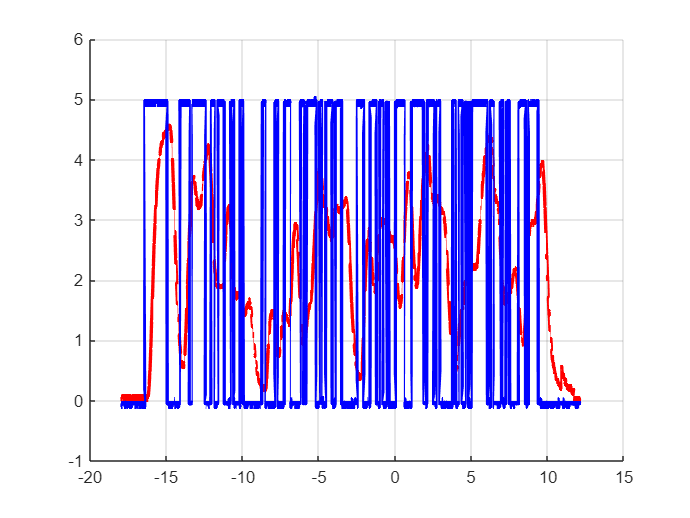

figure();
grid on; hold on;

plot(data_prbs_t, data_prbs_y, 'r', 'LineWidth', 2);
plot(data_prbs_t, data_prbs_u, 'b', 'LineWidth', 2);

starting_index = find(data_prbs_u > 1, 1)-1

starting_index = 1500

ending_index = find(data_prbs_u > 0.7, 1, 'last')+100

ending_index = 27375

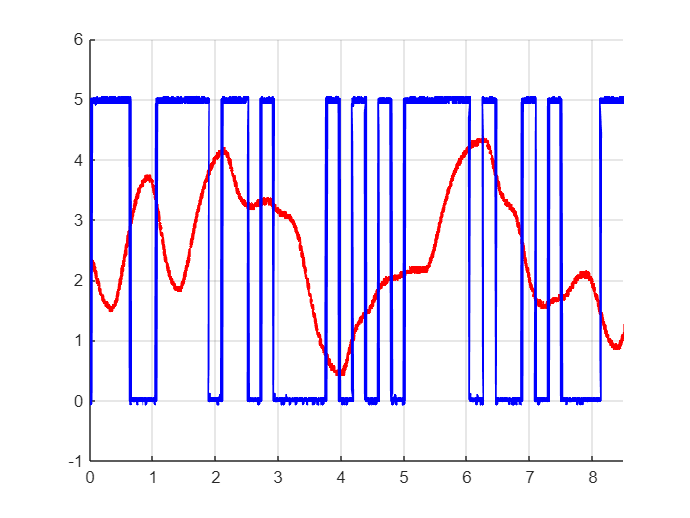


prbs_t = data_prbs_t(starting_index:ending_index);
prbs_y = (data_prbs_y(starting_index:ending_index)-data_prbs_y(1));
prbs_u = (data_prbs_u(starting_index:ending_index)-data_prbs_u(1));

figure();
grid on; hold on;
xlim([0 8.5])

plot(prbs_t, prbs_y, 'r', 'LineWidth', 2);
plot(prbs_t, prbs_u, 'b', 'LineWidth', 2);